# Principal Component Analysis (PCA)

Lorem Ipsum

clc
clear
close all

## Building dataset

Genero distribuzione normale di $n$ punti random con deviazione standard $\sigma$ e media $\mu$. 

In `MATLAB` è possibile generare delle distribuzioni normali utilizzando la funzione `randn();` tale funzione restituisce una distribuzione centrata sullo zero ($\mu = 0$) e deviazione standard unitaria ($\sigma=1$). Qualora si volessero modificare tali parametri sarà sufficiente moltiplicare l'output per la $\sigma$ voluta e aggiungere $\mu$ al risultato del prodotto. La sintassi sarà quindi del tipo `data = sigma.*randn(n,2) + mu`. Si noti che il numero `2` come argomento della funzione `randn()` indica il numero di colonne da generare: una per le ascisse $x$, una per le ordinate $y$.

Nel caso in cui si volesse specificare una deviazione standard differente per le $x$ e per le $y$ per modificare la forma della distribuzione, è possibile porre $\sigma = ( \sigma_x , \sigma_y)$.

In tal modo, se $P$ è la matrice output della funzione `randn()` 

$P=\pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n}$

sarà sufficiente effettuare moltiplicazione elemen-wise (prodotto di Hadamard) $\sigma \odot P$ per modificare la deviazione standard della distribuzione:


$$\sigma \odot P = \pmatrix{\sigma_x & \sigma_y} \odot \pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n} =\pmatrix{ \sigma_x x_1 & \sigma_y y_1 \cr \sigma_x x_2  & \sigma_y y_2 \cr ... & ... \cr  \sigma_x x_n & \sigma_y y_n}$$


In `MATLAB` la sintassi da utilizzare è `sigma.*randn(n,2)` dove `sigma = [2 0.9]` con $\sigma_x = 2$, $\sigma_y = 0.9$.

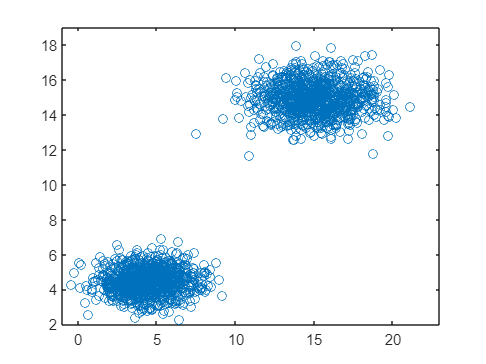

n = 500*2;                % numero di punti
sigma = [2 0.9];        % deviazione standard su x e su y
mu = 15;                % media

% genero primo set di dati (l = 0)
data = sigma.*randn(n,2) + mu;
l = repelem(0,n,1);

% concateno secondo set di dati (l = 1)
data = [data; (sigma*0.8).*randn(n,2) + mu*0.3];
l = [l; repelem(1,n,1)];
x = data(:,1);
y = data(:,2);

% rappresento dati
% hist(x)
% hist(y)

plot(x,y,'o')
xlim([floor(min(x))-1 ceil(max(x))]+1)
ylim([floor(min(y))-1 ceil(max(y))]+1)

Per filtrare le x e le y appartenenti alla prima distribuzione mi basta usare la sintassi `x(l==0)` e `y(l==0)` che sta per "prendimi le righe che rispettano la condizione `l==0`". Procedo quindi a rappresentare queste due distribuzioni

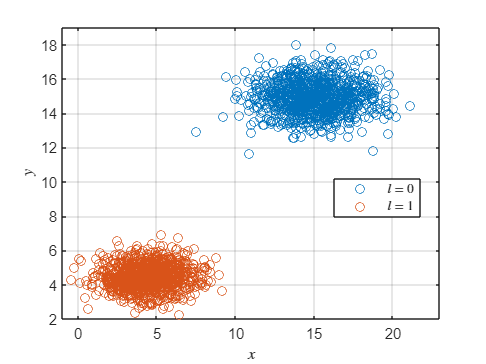

% rappresento la prima distribuzione
plot(x(l==0),y(l==0),'o')
hold on
% rappresento la seconda distribuzione
plot(x(l==1),y(l==1),'o')
hold off
xlim([floor(min(x))-1 ceil(max(x))]+1)
ylim([floor(min(y))-1 ceil(max(y))]+1)
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex','Location','best')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')

Adesso applichiamo una **trasformazione lineare** alle distribuzioni dei dati. Se la matrice della trasformazione $T$ è


$$T=\pmatrix{1 & 1 \cr -1 & 1}$$


e il dataset contiene gli $n$ punti $P$


$$P=\pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n}$$


allora i punti trasformati $P'$ si otterranno eseguendo il prodotto matriciale $T P^T$ dove $P^T$ indica la trasposta di $P$


$$P' =T P^T= \pmatrix{1 & 1 \cr -1 & 1} \pmatrix{x_1 & x_2 & ... & x_n \cr y_1 & y_2 & ... & y_n}$$


% creo matrice trasformazione
linear_trasformation = [1 1; -1 1]

linear_trasformation =      1     1
    -1     1



% applico trasformazione
transformed_data = (linear_trasformation*(data'))'

transformed_data =    32.2263   -2.9962
   31.4465   -2.4894
   28.3306    3.3361
   29.6455    0.3645
   27.9421    0.9158
   31.2390    0.3060
   33.7700   -4.6354
   29.5874    3.0941
   33.3311   -4.4640
   28.5349    0.3960



x = transformed_data(:,1);
y = transformed_data(:,2);

% estremi
endpoints = [floor(min(x))-1 floor(min(y))-1; ceil(max(x))+1 ceil(max(y))+1];
endpoints = array2table(endpoints,"VariableNames",{'x','y'})

endpoints = 2×2 table
    x     y 
    __    __

     2    -8
    38     8


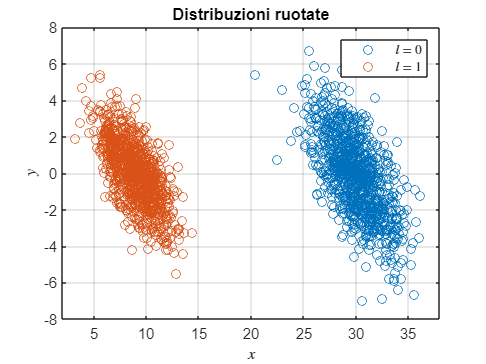


% rappresento distribuzioni ruotate
plot(x(l==0),y(l==0),'o')
hold on
plot(x(l==1),y(l==1),'o')
hold off
% xlim([floor(min(x))-1 ceil(max(x))+1])
% ylim([floor(min(y))-1 ceil(max(y))+1])
xlim([endpoints.x(1) endpoints.x(2)])
ylim([endpoints.y(1) endpoints.y(2)])
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title("Distribuzioni ruotate")

% lavoro solo con l=0
df = transformed_data(l==0,:)

df =    32.2263   -2.9962
   31.4465   -2.4894
   28.3306    3.3361
   29.6455    0.3645
   27.9421    0.9158
   31.2390    0.3060
   33.7700   -4.6354
   29.5874    3.0941
   33.3311   -4.4640
   28.5349    0.3960



% centro i dati sottraendo la media
dfm=mean(df)

dfm =    30.0080   -0.1143


B = df-dfm

B =     2.2183   -2.8820
    1.4385   -2.3751
   -1.6774    3.4504
   -0.3625    0.4787
   -2.0658    1.0300
    1.2310    0.4203
    3.7620   -4.5211
   -0.4206    3.2083
    3.3231   -4.3498
   -1.4731    0.5102



% ottengo i limiti degli intervalli
limits_margin = 2;
endpoints = [floor(min(B(:,1)))-limits_margin ceil(max(B(:,2)))+limits_margin floor(min(B(:,2)))-limits_margin ceil(max(B(:,1)))+limits_margin];

% rappresento distribuzioni centrate
scatter(B(:,1),B(:,2), 'filled', 'MarkerFaceAlpha', 0.5,'MarkerEdgeColor','none')
% scatter(df(:,1),df(:,2), 'filled', 'MarkerFaceAlpha', 0.5,'MarkerEdgeColor','none')
hold on
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
% axis([-7 7 -9 9])
axis(endpoints)
box off
grid on
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

## SVD

$U$ è una matrice le cui colonne contengono gli autovettori;

$S$ è la matrice di covarianza (?)

[U,S,V] = svd(B,'econ')

U =    -0.0413   -0.0116
   -0.0309   -0.0163
    0.0415    0.0309
    0.0068    0.0020
    0.0251   -0.0180
   -0.0066    0.0288
   -0.0671   -0.0133
    0.0294    0.0486
   -0.0622   -0.0179
    0.0161   -0.0168


S =    87.2741         0
         0   40.5877


V =    -0.7073    0.7069
    0.7069    0.7073


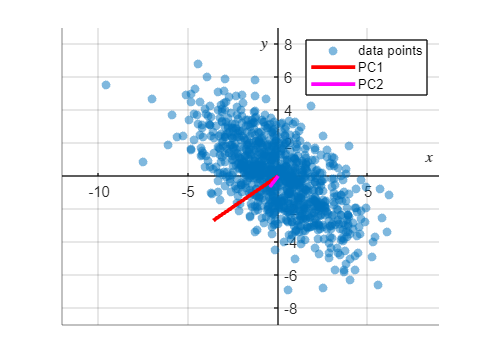


% plot principal components U(:,1)S(1,1) and U(:,2)S(2,2)
% plot([dfm(1) dfm(1)+U(1,1)*S(1,1)],[dfm(2) dfm(2)+U(2,1)*S(1,1)],"r-",'LineWidth',2.5)
% plot([dfm(1) dfm(1)+U(1,2)*S(2,2)],[dfm(2) dfm(2)+U(2,2)*S(2,2)],"r-",'LineWidth',2.5)
plot([0 U(1,1)*S(1,1)],[0 U(2,1)*S(1,1)],"r-",'LineWidth',2.5)
plot([0 U(1,2)*S(2,2)],[0 U(2,2)*S(2,2)],"m-",'LineWidth',2.5)
hold off
legend("data points","PC1","PC2")

## Centering data

per centrare bla bla

% calcolo media
xm = mean(x);
ym = mean(y);
% mean_data = mean(tranformed_data,2)

% centro i dati
xc = x-xm;
yc = y-ym;

% aggiorno estremi intervalli
endpoints = [floor(min(xc))-1 floor(min(yc))-1; ceil(max(xc))+1 ceil(max(yc))+1];
endpoints = array2table(endpoints,"VariableNames",{'x','y'})

% plotto distribuzione centrata
plot(xc(l==0),yc(l==0),'o')
hold on
plot(xc(l==1),yc(l==1),'o')
% aggiungo assi
plot(linspace(endpoints.x(1),endpoints.x(2),2),repelem(0,2),"Color","black")
plot(repelem(0,2), linspace(endpoints.y(1),endpoints.y(2),2),"Color","black")
hold off
xlim([endpoints.x(1) endpoints.x(2)])
ylim([endpoints.y(1) endpoints.y(2)])

grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex','Location','best')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title("Distribuzioni centrate nell'origine")

## Note

Questo documento è stato generato convertendo in markdown un `MATLAB` livescript utilizzano il tool `livescript2markdown`

% esporto in md
livescript2markdown("pca_v1.mlx","../README.md","AddMention",true,"Format","github")